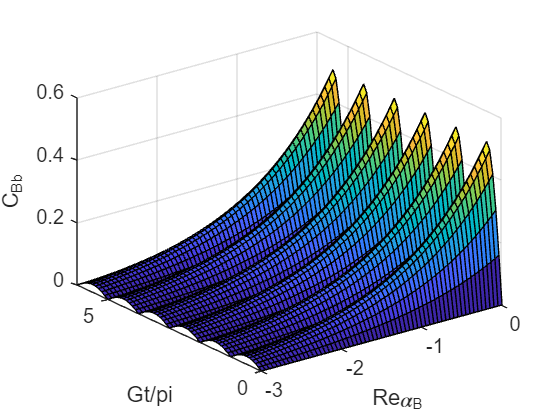

%Concurrences for Coherent States

alpha1=pi/4;
alpha2=pi/6;
alpha3=pi/12;

[Re_alpha_A_mesh, Gt_mesh]=meshgrid(0:-0.05:-3,0:0.1*pi:6*pi);
%PART1 PHI STATE--------------------------------------------------
%C_AB(t)-----------------------------------------------------------
Con_AB_1_mesh=(cos(Gt_mesh/2)).^2.*(abs(sin(2*alpha1))-2*((sin(Gt_mesh/2))).^2*cos(alpha1)^2.*exp(Re_alpha_A_mesh+Re_alpha_A_mesh));
Con_AB_2_mesh=(cos(Gt_mesh/2)).^2.*(abs(sin(2*alpha2))-2*((sin(Gt_mesh/2))).^2*cos(alpha2)^2.*exp(Re_alpha_A_mesh+Re_alpha_A_mesh));
Con_AB_3_mesh=(cos(Gt_mesh/2)).^2.*(abs(sin(2*alpha3))-2*((sin(Gt_mesh/2))).^2*cos(alpha3)^2.*exp(Re_alpha_A_mesh+Re_alpha_A_mesh));

% figure;
% surf(Re_alpha_A_mesh, Gt_mesh/pi, Con_AB_1_mesh);
% xlabel('Re{\alpha_A}');
% ylabel('Gt/pi');
% zlabel('C_{AB(t)}');
% 
% figure;
% surf(Re_alpha_A_mesh, Gt_mesh/pi, Con_AB_2_mesh);
% xlabel('Re{\alpha_A}');
% ylabel('Gt/pi');
% zlabel('C_{AB(t)}');
% 
% figure;
% surf(Re_alpha_A_mesh, Gt_mesh/pi, Con_AB_3_mesh);
% xlabel('Re{\alpha_A}');
% ylabel('Gt/pi');
% zlabel('C_{AB(t)}');

%Cab------------------------------------------------------------------
Con_ab_1_mesh=exp(Re_alpha_A_mesh+Re_alpha_A_mesh).*(cos(Gt_mesh/2)).^2.*(abs(sin(2*alpha1))-2*((sin(Gt_mesh/2))).^2*cos(alpha1)^2);
Con_ab_2_mesh=exp(Re_alpha_A_mesh+Re_alpha_A_mesh).*(cos(Gt_mesh/2)).^2.*(abs(sin(2*alpha2))-2*((sin(Gt_mesh/2))).^2*cos(alpha2)^2);
Con_ab_3_mesh=exp(Re_alpha_A_mesh+Re_alpha_A_mesh).*(cos(Gt_mesh/2)).^2.*(abs(sin(2*alpha3))-2*((sin(Gt_mesh/2))).^2*cos(alpha3)^2);

% figure;
% surf(Re_alpha_A_mesh, Gt_mesh/pi, Con_ab_1_mesh);
% xlabel('Re{\alpha_A}');
% ylabel('Gt/pi');
% zlabel('C_{ab}');
% 
% figure;
% surf(Re_alpha_A_mesh, Gt_mesh/pi, Con_ab_2_mesh);
% xlabel('Re{\alpha_A}');
% ylabel('Gt/pi');
% zlabel('C_{ab}');
% 
% figure;
% surf(Re_alpha_A_mesh, Gt_mesh/pi, Con_ab_3_mesh);
% xlabel('Re{\alpha_A}');
% ylabel('Gt/pi');
% zlabel('C_{ab}');

%CAb-------------------------------------------
Con_Ab_1_mesh=1/2*cos(alpha1)^2*abs(sin(Gt_mesh)).*exp(Re_alpha_A_mesh).*[2*abs(tan(alpha1))-exp(Re_alpha_A_mesh).*abs(sin(Gt_mesh))];
Con_Ab_2_mesh=1/2*cos(alpha2)^2*abs(sin(Gt_mesh)).*exp(Re_alpha_A_mesh).*[2*abs(tan(alpha2))-exp(Re_alpha_A_mesh).*abs(sin(Gt_mesh))];
Con_Ab_3_mesh=1/2*cos(alpha3)^2*abs(sin(Gt_mesh)).*exp(Re_alpha_A_mesh).*[2*abs(tan(alpha3))-exp(Re_alpha_A_mesh).*abs(sin(Gt_mesh))];

% figure;
% surf(Re_alpha_A_mesh, Gt_mesh/pi, Con_Ab_1_mesh);
% xlabel('Re{\alpha_A}');
% ylabel('Gt/pi');
% zlabel('C_{Ab}');
% 
% figure;
% surf(Re_alpha_A_mesh, Gt_mesh/pi, Con_Ab_2_mesh);
% xlabel('Re{\alpha_A}');
% ylabel('Gt/pi');
% zlabel('C_{Ab}');
% 
% figure;
% surf(Re_alpha_A_mesh, Gt_mesh/pi, Con_Ab_3_mesh);
% xlabel('Re{\alpha_A}');
% ylabel('Gt/pi');
% zlabel('C_{Ab}');

%CAa-----------------------------------------------------
Con_Aa_1_mesh=cos(alpha1)^2*abs(sin(Gt_mesh)).*exp(Re_alpha_A_mesh).*(exp(2*Re_alpha_A_mesh).*sin(Gt_mesh/2).^2+cos(Gt_mesh/2).^2);
Con_Aa_2_mesh=cos(alpha2)^2*abs(sin(Gt_mesh)).*exp(Re_alpha_A_mesh).*(exp(2*Re_alpha_A_mesh).*sin(Gt_mesh/2).^2+cos(Gt_mesh/2).^2);
Con_Aa_3_mesh=cos(alpha3)^2*abs(sin(Gt_mesh)).*exp(Re_alpha_A_mesh).*(exp(2*Re_alpha_A_mesh).*sin(Gt_mesh/2).^2+cos(Gt_mesh/2).^2);

% figure;
% surf(Re_alpha_A_mesh, Gt_mesh/pi, Con_Aa_1_mesh);
% xlabel('Re{\alpha_A}');
% ylabel('Gt/pi');
% zlabel('C_{Aa}');
% 
% figure;
% surf(Re_alpha_A_mesh, Gt_mesh/pi, Con_Aa_2_mesh);
% xlabel('Re{\alpha_A}');
% ylabel('Gt/pi');
% zlabel('C_{Aa}');
% 
% figure;
% surf(Re_alpha_A_mesh, Gt_mesh/pi, Con_Aa_3_mesh);
% xlabel('Re{\alpha_A}');
% ylabel('Gt/pi');
% zlabel('C_{Aa}');

%PART2 PSI STATES-------------------------------------------
%CAB-------------------------------------------------------
Con_Psi_AB_1=abs(sin(2*alpha1))*cos(Gt_mesh/2).^2;
Con_Psi_AB_2=abs(sin(2*alpha2))*cos(Gt_mesh/2).^2;
Con_Psi_AB_3=abs(sin(2*alpha3))*cos(Gt_mesh/2).^2;

% figure;
% surf(Re_alpha_A_mesh, Gt_mesh/pi, Con_Psi_AB_1);
% xlabel('Re{\alpha_A}');
% ylabel('Gt/pi');
% zlabel('C_{AB}');
% 
% figure;
% surf(Re_alpha_A_mesh, Gt_mesh/pi, Con_Psi_AB_2);
% xlabel('Re{\alpha_A}');
% ylabel('Gt/pi');
% zlabel('C_{AB}');
% 
% figure;
% surf(Re_alpha_A_mesh, Gt_mesh/pi, Con_Psi_AB_3);
% xlabel('Re{\alpha_A}');
% ylabel('Gt/pi');
% zlabel('C_{AB}');

%Cab---------------------------------------------------------
Con_Psi_ab_1=abs(sin(2*alpha1))*exp(Re_alpha_A_mesh+Re_alpha_A_mesh).*sin(Gt_mesh/2).^2;
Con_Psi_ab_2=abs(sin(2*alpha2))*exp(Re_alpha_A_mesh+Re_alpha_A_mesh).*sin(Gt_mesh/2).^2;
Con_Psi_ab_3=abs(sin(2*alpha3))*exp(Re_alpha_A_mesh+Re_alpha_A_mesh).*sin(Gt_mesh/2).^2;

% figure;
% surf(Re_alpha_A_mesh, Gt_mesh/pi, Con_Psi_ab_1);
% xlabel('Re{\alpha_A}');
% ylabel('Gt/pi');
% zlabel('C_{ab}');
% 
% figure;
% surf(Re_alpha_A_mesh, Gt_mesh/pi, Con_Psi_ab_2);
% xlabel('Re{\alpha_A}');
% ylabel('Gt/pi');
% zlabel('C_{ab}');
% 
% figure;
% surf(Re_alpha_A_mesh, Gt_mesh/pi, Con_Psi_ab_3);
% xlabel('Re{\alpha_A}');
% ylabel('Gt/pi');
% zlabel('C_{ab}');

%CAb---------------------------------------------------------------
Con_Psi_Ab_1=abs(sin(2*alpha1))*exp(Re_alpha_A_mesh).*abs(sin(Gt_mesh));
Con_Psi_Ab_2=abs(sin(2*alpha2))*exp(Re_alpha_A_mesh).*abs(sin(Gt_mesh));
Con_Psi_Ab_3=abs(sin(2*alpha3))*exp(Re_alpha_A_mesh).*abs(sin(Gt_mesh));

% figure;
% surf(Re_alpha_A_mesh, Gt_mesh/pi, Con_Psi_Ab_1);
% xlabel('Re{\alpha_B}');
% ylabel('Gt/pi');
% zlabel('C_{ab}');
% 
% figure;
% surf(Re_alpha_A_mesh, Gt_mesh/pi, Con_Psi_Ab_2);
% xlabel('Re{\alpha_B}');
% ylabel('Gt/pi');
% zlabel('C_{ab}');
% 
% figure;
% surf(Re_alpha_A_mesh, Gt_mesh/pi, Con_Psi_Ab_3);
% xlabel('Re{\alpha_B}');
% ylabel('Gt/pi');
% zlabel('C_{ab}');

%CAa------------------------------------------------------
Con_Psi_Aa_1=cos(alpha1).^2*exp(Re_alpha_A_mesh).*abs(sin(Gt_mesh));
Con_Psi_Aa_2=cos(alpha2).^2*exp(Re_alpha_A_mesh).*abs(sin(Gt_mesh));
Con_Psi_Aa_3=cos(alpha3).^2*exp(Re_alpha_A_mesh).*abs(sin(Gt_mesh));

% figure;
% surf(Re_alpha_A_mesh, Gt_mesh/pi, Con_Psi_Aa_1);
% xlabel('Re{\alpha_A}');
% ylabel('Gt/pi');
% zlabel('C_{Aa}');
% 
% figure;
% surf(Re_alpha_A_mesh, Gt_mesh/pi, Con_Psi_Aa_2);
% xlabel('Re{\alpha_A}');
% ylabel('Gt/pi');
% zlabel('C_{Aa}');
% 
% figure;
% surf(Re_alpha_A_mesh, Gt_mesh/pi, Con_Psi_Aa_3);
% xlabel('Re{\alpha_A}');
% ylabel('Gt/pi');
% zlabel('C_{Aa}');

%CBb--------------------------------------------------------------
Con_Psi_Bb_1=sin(alpha1).^2*exp(Re_alpha_A_mesh).*abs(sin(Gt_mesh));
Con_Psi_Bb_2=sin(alpha2).^2*exp(Re_alpha_A_mesh).*abs(sin(Gt_mesh));
Con_Psi_Bb_3=sin(alpha3).^2*exp(Re_alpha_A_mesh).*abs(sin(Gt_mesh));

% figure;
% surf(Re_alpha_A_mesh, Gt_mesh/pi, Con_Psi_Bb_1);
% xlabel('Re{\alpha_B}');
% ylabel('Gt/pi');
% zlabel('C_{Bb}');

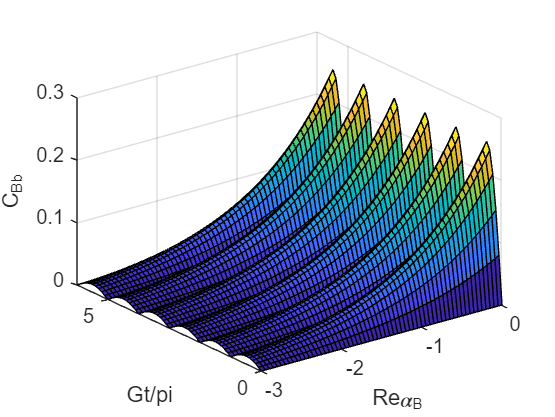

% 
% figure;
% surf(Re_alpha_A_mesh, Gt_mesh/pi, Con_Psi_Bb_2);
% xlabel('Re{\alpha_B}');
% ylabel('Gt/pi');
% zlabel('C_{Bb}');

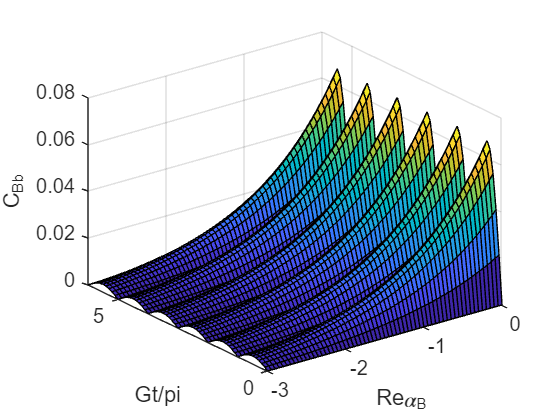

% 
% figure;
% surf(Re_alpha_A_mesh, Gt_mesh/pi, Con_Psi_Bb_3);
% xlabel('Re{\alpha_B}');
% ylabel('Gt/pi');
% zlabel('C_{Bb}');